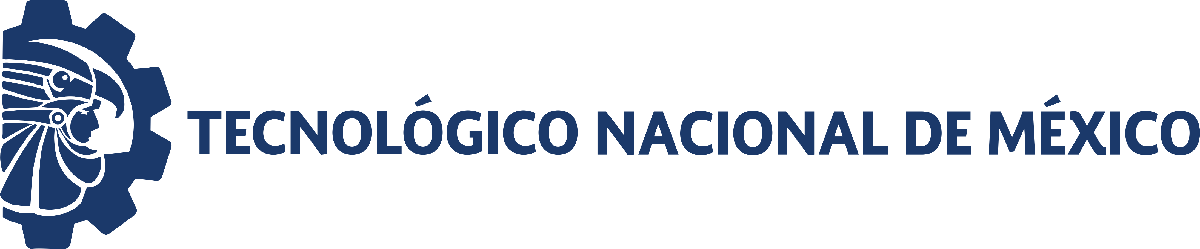                                 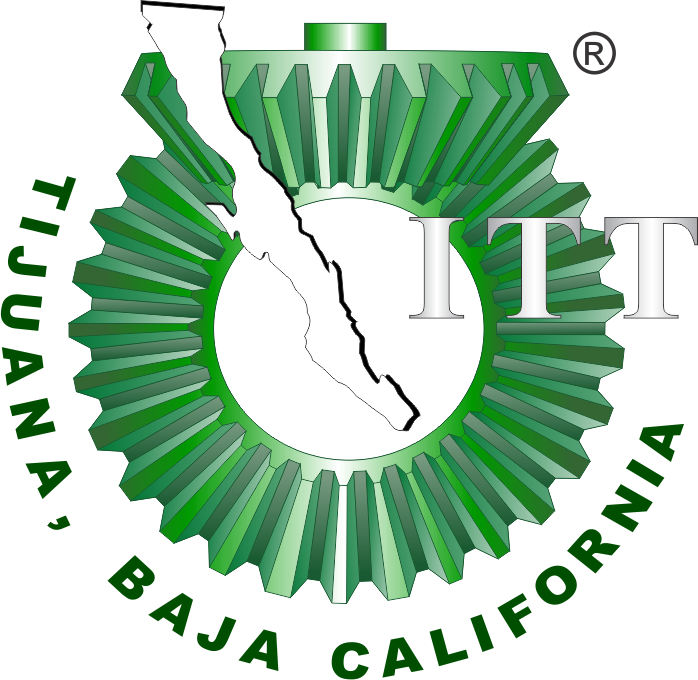

# Proyecto Final: Sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

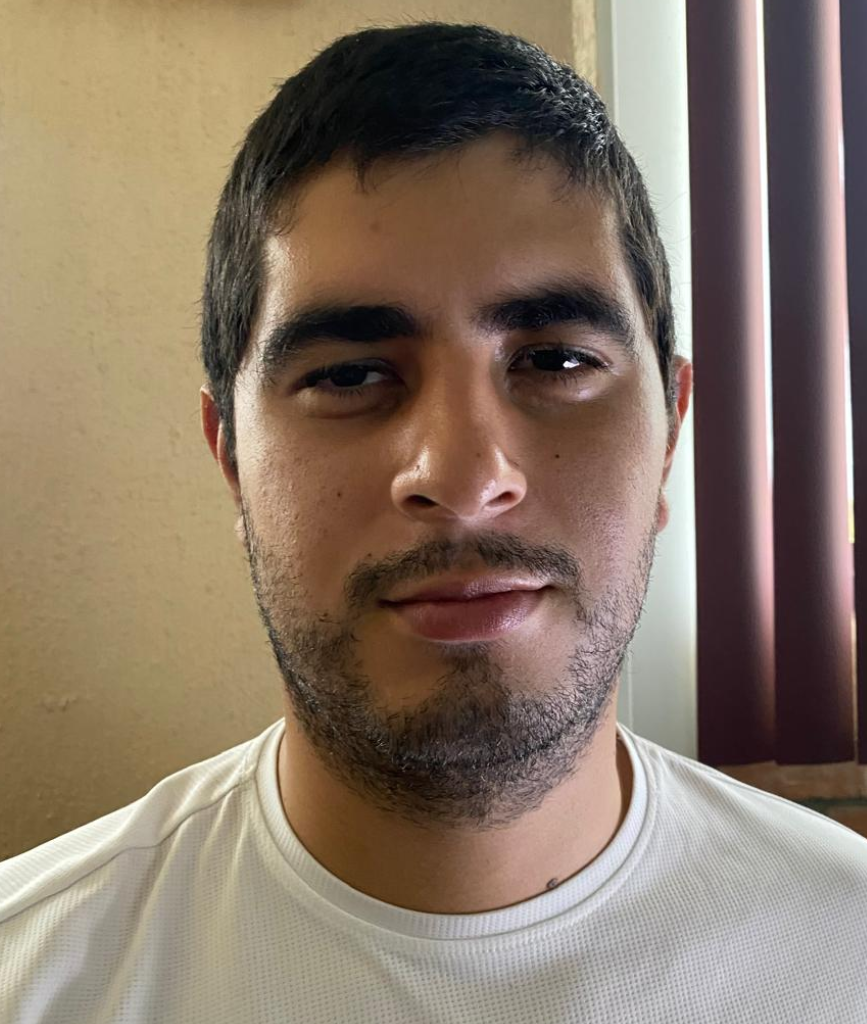

Nombre del alumno: **Edgar Iván Rivas Rosas**

Número de control: **21212748**

Correo institucional:** l21212748@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "20";
file = "sysF_LC___";
open_system(file);
parameters.StopTime = tend;
parameters.Solver = "ode2";
parameters.MaxStep = "1E-5";
Controlador = "PI";

## Rendimiento del controlador 

kP = 2

kI = 4

## Secreción natural de CRH

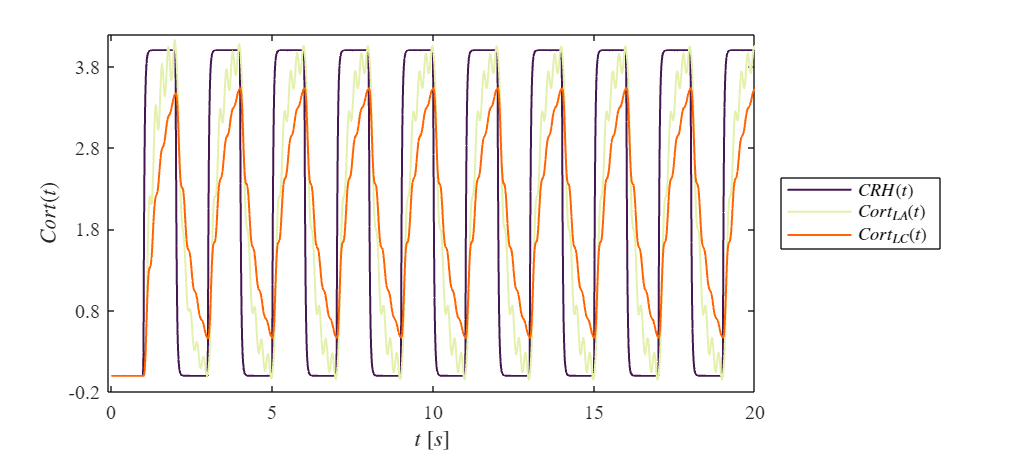

Signal='Secreción natural';
x1 = sim(file,parameters);
plotsignals(x1.t,x1.CRH,x1.Cort1,x1.Cort2,x1.Cort3,Signal)

## Función: Respuesta a las señales

function plotsignals(t,CRH,Cort1,Cort2,Cort3,Signal)
    set(figure(), "Color", "w")
    set(gcf,"units","Centimeters","Position",[1,1,18,8])
    set(gca,"FontName","Times New Roman")
    fontsize(10,"points")
    morado =[68/255, 23/255, 82/255];
    %rosa =[255/255, 116/255, 139/255];
    naranja =[255/255, 101/255, 0/255];
    verde = [228/255, 241/255, 172/255];
    hold on; grid off; box on

    plot(t,Cort1,"LineWidth",1,"Color",morado)
    plot(t,Cort2,"LineWidth",1,"Color",verde)
    plot(t,Cort3,"LineWidth",1,"Color",naranja)

    xlabel('$t$ $[s]$', 'Interpreter','Latex')
    ylabel('$Cort(t)$', 'Interpreter','Latex')

    L = legend("$CRH(t)$","$Cort_{LA}(t)$","$Cort_{LC}(t)$");
    set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")

    
    xlim([-0.1, 20]); xticks(0:5:20)
    ylim([-0.2,4.2]); yticks(-0.2:1:4)
    
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end